# Project Team 3

**Team:** Alexander Wang (aw3494) & Nicholas Fioravanti (nef46)

#### This .mlx file aims to generate replicated results for the SEIR model in Hou et al. as well as to create a randomized contact network matrix, both in the attempt to simulate the transmission of COVID-19 within communities and affected groups.

# COVID SEIR Model

Using the SEIR Hou et al. Model: 

#### Generate Approximated Time Course of COVID Transmission

% Input for ode45 function
input_vector = [11080778 193 27 2]; % [Susceptible, Exposed, Infectious, Recovered] 
time = [0 365]; % time in days

% Ode45 function 
[T,Y] = ode45(@basic_model, time, input_vector);

#### Plot SEIR Model Results Over Time Course for Individuals

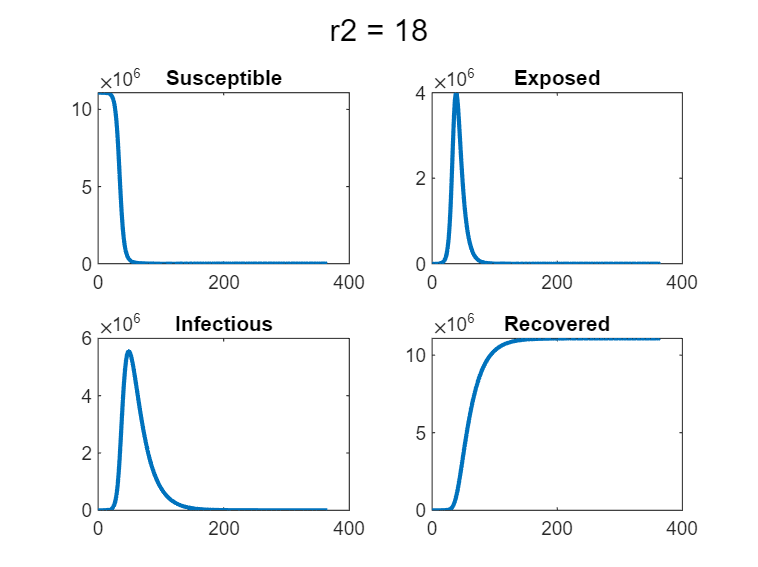

% Plot changes in groups for SEIR covid model for r = 18 

% Create figure 
figure 

% Hold onto the same figure 
hold on 

% Provide figure title
sgtitle('r2 = 18') 

% Create 4 subplots, and target the first subspace
subplot(2,2,1) 

% Plot susceptible
plot(T,Y(:,1), 'LineWidth', 2) 

% Add title
title('Susceptible') 

% Target second subspace
subplot(2,2,2) 

% Plot exposed
plot(T,Y(:,2), 'LineWidth', 2) 

% Add title
title('Exposed') 

% Target third subspace
subplot(2,2,3) 

% Plot infected
plot(T,Y(:,3), 'LineWidth', 2) 

% Add title
title('Infectious') 

% Target fourth subspace
subplot(2,2,4) 

% Plot recovered
plot(T,Y(:,4), 'LineWidth', 2) 

% Add title
title('Recovered') 

% Let go of figure
hold off 

#### Plot SEIR Model Results Over Time Course for Proportions

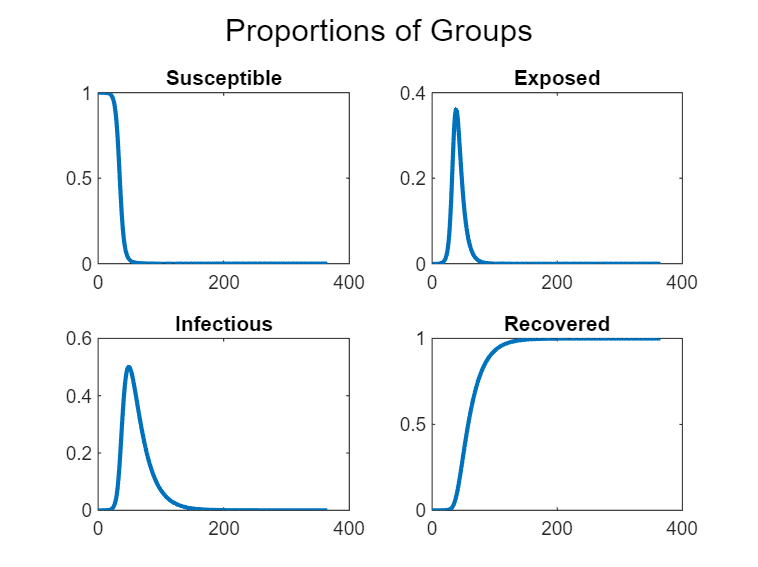

% Plot changes in groups for covid model for r = 18 

% Create new figure 
figure

% Hold onto figure 
hold on 

% Create figure title 
sgtitle('Proportions of Groups')

% Target first subspace of new figure 
subplot(2,2,1) 

% Plot proportion of susceptible 
plot(T,Y(:,1)./11081000, 'LineWidth', 2)
title('Susceptible')

% Target second subspace of new figure 
subplot(2,2,2)

% Plot proportion of exposed
plot(T,Y(:,2)./11081000, 'LineWidth', 2)
title('Exposed')

% Target third subspace of new figure 
subplot(2,2,3)

% Plot proportion of infected
plot(T,Y(:,3)./11081000, 'LineWidth', 2)
title('Infectious')

% Target fourth subspace of new figure 
subplot(2,2,4)

% Plot proportion of recovered
plot(T,Y(:,4)./11081000, 'LineWidth', 2)
title('Recovered')

% Hold off of figure
hold off

#### Generate Approximated Time Course of COVID Transmission Across Different Contact Rates (r2)

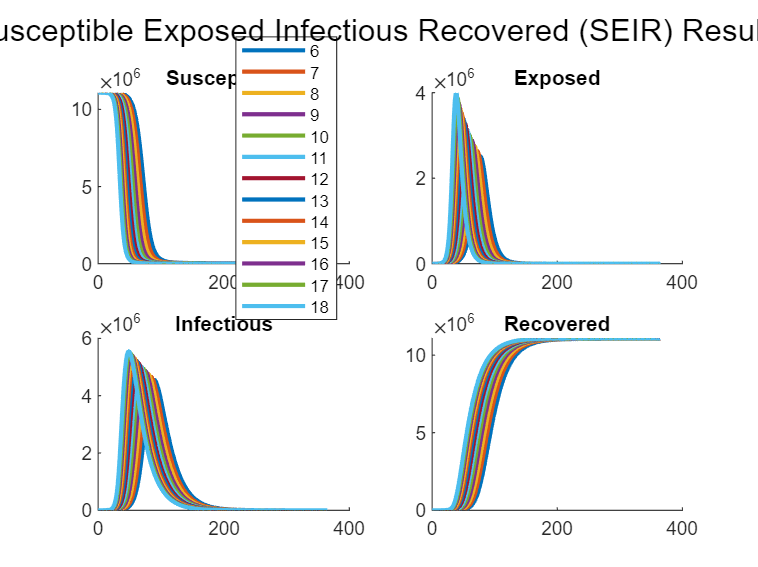

% Create a new figure 
figure

% Hold onto figure
hold on 

% Vary r2 from 6 to 18
rate_varying = 6:18;

% Iterate through the covid model with different r2 values and plot the
% results 
for l = rate_varying

    % Simulate time course of transmission with input of r2 as the
    % iterative l
    [T,Y] = ode45(@(t,y) basic_model(t,y,l), time, input_vector);   

    % Target first subplot
    subplot(2,2,1)

    % Hold onto subplot
    hold on

    % Plot susceptible individuals
    plot(T,Y(:,1), 'LineWidth', 2)
    
    % Add title
    title('Susceptible')

    % Target second subplot
    subplot(2,2,2)

    % Hold onto subplot
    hold on 

    % Plot exposed individuals
    plot(T,Y(:,2), 'LineWidth', 2)

    % Add title
    title('Exposed')

    % Target third subplot
    subplot(2,2,3)

    % Hold onto subplot
    hold on 

    % Plot infected individuals
    plot(T,Y(:,3), 'LineWidth', 2)

    % Add title
    title('Infectious')

    % Target fourth subplot
    subplot(2,2,4)

    % Hold onto subplot
    hold on 

    % Plot recovered individuals
    plot(T,Y(:,4), 'LineWidth', 2)

    % Add title
    title('Recovered')

    % Find the peak individuals per category and at what times they
    % occurred for each r2 value 
    maxima(:,l-5) = [max(Y(:,1)); max(Y(:,2)); max(Y(:,3)); max(Y(:,4))];
    times(:,l-5) = [T(find(Y(:,1) == max(Y(:,1)))), T(find(Y(:,2) == max(Y(:,2)))), T(find(Y(:,3) == max(Y(:,3)))), T(find(Y(:,4) == max(Y(:,4))))];
end

% Return to the first subplot
subplot(2,2,1)

% Hold onto the first subplot
hold on 

% Add an overall title 
sgtitle('Susceptible Exposed Infectious Recovered (SEIR) Results')

% Add a legend
legend({'6', '7', '8', '9', '10', '11', '12', '13', '14', '15', '16', '17', '18'}, 'Location','best')

% Hold off
hold off

#### Generate Approximated Time Course of COVID Transmission Across Different Contact Rates (r2) and Use Proportions Instead

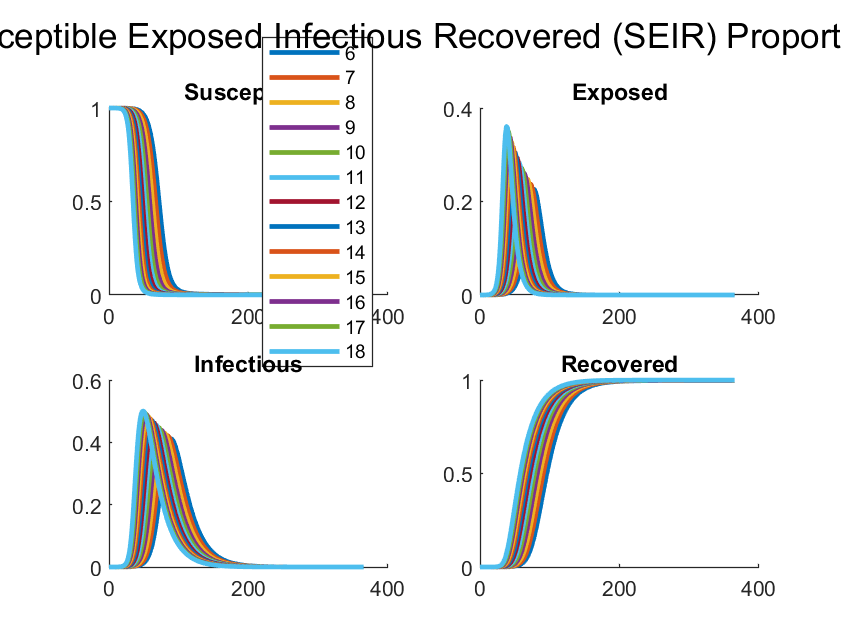

% Create a new figure 
figure

% Hold onto figure
hold on 

% Vary r2 from 6 to 18
rate_varying = 6:18;

% Iterate through the covid model with different r2 values and plot the
% results 

% comments are similar to the previous code, but using division with the
% total number of individuals
for l = rate_varying
    [T,Y] = ode45(@(t,y) basic_model(t,y,l), time, input_vector);   
    subplot(2,2,1)
    hold on
    plot(T,Y(:,1)./11081000, 'LineWidth', 2)
    title('Susceptible')
    subplot(2,2,2)
    hold on 
    plot(T,Y(:,2)./11081000, 'LineWidth', 2)
    title('Exposed')
    subplot(2,2,3)
    hold on 
    plot(T,Y(:,3)./11081000, 'LineWidth', 2)
    title('Infectious')
    subplot(2,2,4)
    hold on 
    plot(T,Y(:,4)./11081000, 'LineWidth', 2)
    title('Recovered')

    % Find the peak individuals per category and at what times they
    % occurred for each r2 value 
    maxima(:,l-5) = [max(Y(:,1)); max(Y(:,2)); max(Y(:,3)); max(Y(:,4))];
    times(:,l-5) = [T(find(Y(:,1) == max(Y(:,1)))), T(find(Y(:,2) == max(Y(:,2)))), T(find(Y(:,3) == max(Y(:,3)))), T(find(Y(:,4) == max(Y(:,4))))];
end
subplot(2,2,1)
hold on 
sgtitle('Susceptible Exposed Infectious Recovered (SEIR) Proportions')
legend({'6', '7', '8', '9', '10', '11', '12', '13', '14', '15', '16', '17', '18'}, 'Location','best')
hold off

## Results

#### Table Creation of Comparison of Time and Individuals over Different r2 Rates 

% Create a table of the r2 values with their respective peak time for both
% exposed and infectious individuals 
Table2 = table(rate_varying', times(2,:)', maxima(2,:)', times(3,:)', maxima(3,:)', 'VariableNames', {'r2', 'Peak Time (Days) for Exposed Individuals', 'Peak Exposed Individuals', 'Peak Time (Days) for Infectious Individuals', 'Peak Infectious Individuals'})

Table2 = 13×5 table
    r2    Peak Time (Days) for Exposed Individuals    Peak Exposed Individuals    Peak Time (Days) for Infectious Individuals    Peak Infectious Individuals
    __    ________________________________________    ________________________    ___________________________________________    ___________________________

     6                     76.432                             2.512e+06                             88.064                               4.5596e+06         
     7                     72.076                            2.6374e+06                             83.915                               4.6706e+06         
     8                      67.98                            2.7563e+06                              78.78                               4.7762e+06         
     9                  

#### Comparison of Exposure vs. Infectious Individuals for Basic Model

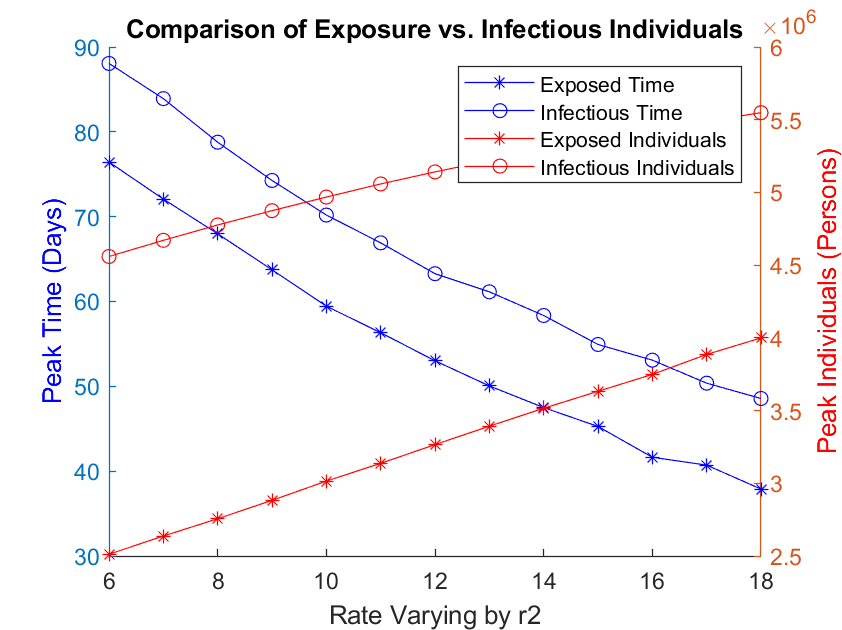

% Creat new figure 
figure

% Hold onto the figure 
hold on 

% On the left y-axis 
yyaxis left

% Plot the times at which peak occur
plot(rate_varying', times(2,:)', '-b*', rate_varying', times(3,:)', '-bo')

% Provide x and y labels
xlabel('Rate Varying by r2')
ylabel('Peak Time (Days)', 'Color', 'b')

% Provide a title 
title('Comparison of Exposure vs. Infectious Individuals')

% On the right y-axis 
yyaxis right 

% Plot the max individuals
plot(rate_varying', maxima(2,:)', '-r*', rate_varying', maxima(3,:)', '-ro')

% Provide a label on the y-axis
ylabel('Peak Individuals (Persons)', 'Color', 'r')

% Provide a legend
legend('Exposed Time', 'Infectious Time', 'Exposed Individuals', 'Infectious Individuals')

#### Table Creation of Comparison of Time and Proportions over Different r2 Rates 

% Create a table of the r2 values with their respective peak time for both
% exposed and infectious individuals 
TableProportions = table(rate_varying', times(2,:)', (maxima(2,:)')./11081000, times(3,:)', (maxima(3,:)')./11081000, 'VariableNames', {'r2', 'Peak Time (Days) for Exposed Individuals', 'Peak Exposed Individuals', 'Peak Time (Days) for Infectious Individuals', 'Peak Infectious Individuals'})

TableProportions = 13×5 table
    r2    Peak Time (Days) for Exposed Individuals    Peak Exposed Individuals    Peak Time (Days) for Infectious Individuals    Peak Infectious Individuals
    __    ________________________________________    ________________________    ___________________________________________    ___________________________

     6                     76.432                              0.2267                               88.064                                 0.41148          
     7                     72.076                             0.23801                               83.915                                 0.42149          
     8                      67.98                             0.24874                                78.78                                 0.43103          
     9        

#### Comparison of Exposure vs. Infectious Individuals for Basic Model (Proportions)

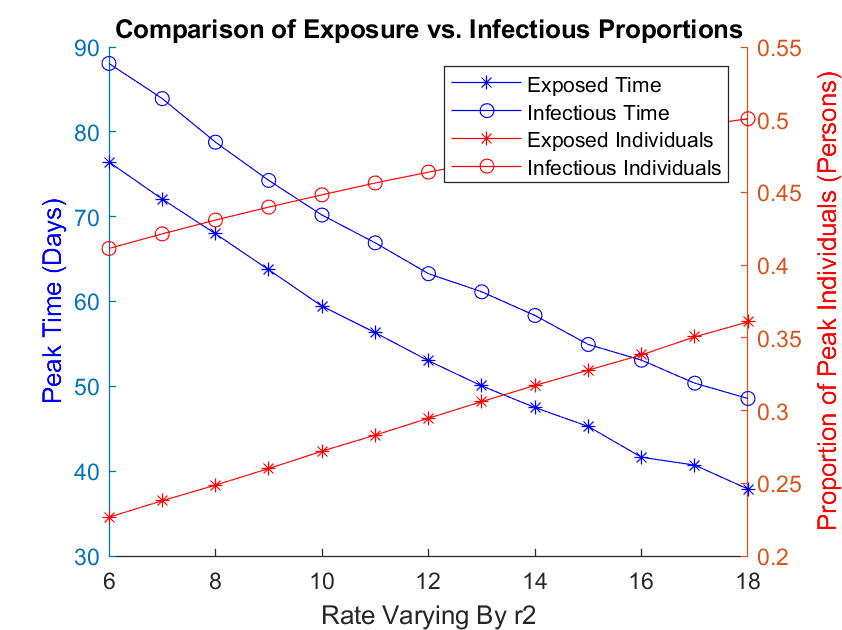

% New figure 
figure

% Hold on 
hold on 

% On left y-axis
yyaxis left

% Plot times
plot(rate_varying', times(2,:)', '-b*', rate_varying', times(3,:)', '-bo')

% Add labels for axes
xlabel('Rate Varying By r2')
ylabel('Peak Time (Days)', 'Color', 'b')

% Add title
title('Comparison of Exposure vs. Infectious Proportions')

% On right y-axis 
yyaxis right 

% Plot proportions
plot(rate_varying', (maxima(2,:)')./11081000, '-r*', rate_varying', (maxima(3,:)')./11081000, '-ro')

% Add y-label
ylabel('Proportion of Peak Individuals (Persons)', 'Color', 'r')

% Add legend
legend('Exposed Time', 'Infectious Time', 'Exposed Individuals', 'Infectious Individuals')

# Contact Network Simulation

This .mlx file establishes a radonmized contact network matrix that attempts to simulate the transmission of covid-19 amongst susceptible, infected, exposed, hospitalized, deceased, and recovered individuals. A parametric analysis is performed with respect to the level of social distancing/isolating or quarantining that occurs while susceptible.  

#### Generate Basic Results from SEIR Model for later graphing/comparison with the network model

%% Basic Model Implementation
% Input for ode45 function
input_vector = [11080778 193 27 2]; % [Susceptible, Exposed, Infectious, Recovered] 
time = [0 365]; % days

% Ode45 function for transmission approximation
[T,Y] = ode45(@basic_model, time, input_vector);

## Step 1. Set up Network Representation

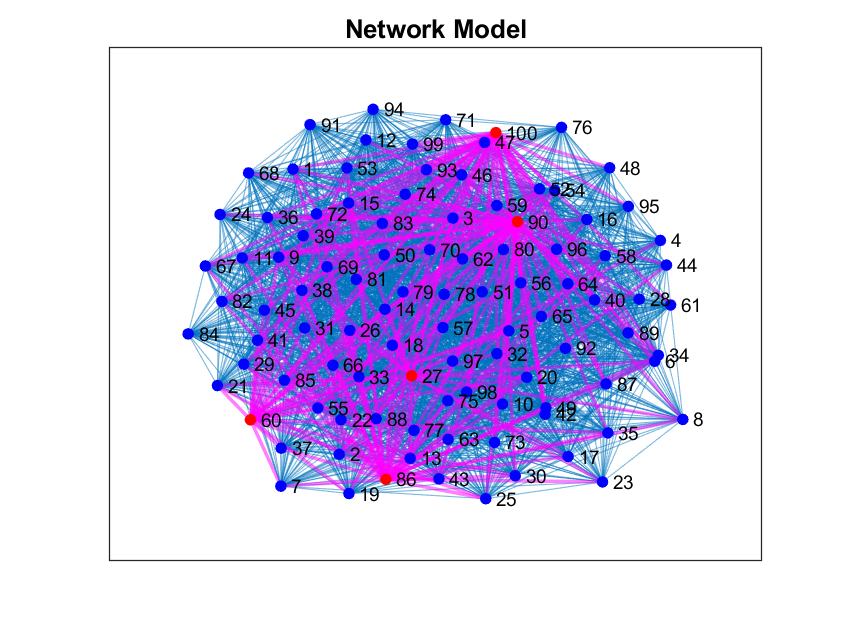

% Number of individuals
N = 100;

% Random symmetric matrix
network = randi([0, 1], N);
network = triu(network, 1);
network = network + network';

% Initialize the state of individuals (0 = Susceptible, 1 = Infected)
state = zeros(N, 1);

% Create random ages for individuals in contact network
age = ones(N,1); 
for p = 1:size(age,1)
    age(p) = randi(80);
end

% Randomly assign a few individuals as Infected
num_initially_infected = 0.05*N;
infected_indices = randperm(N, num_initially_infected);
state(infected_indices) = 1;

% Initial stats:
initial_infected_proportion = sum(state)/N; 
initial_susceptible_proportion = sum(state==0)/N;

G = graph(network, 'upper'); % Create a graph object

% Assign states to nodes in the graph
for i = 1:N
    if state(i) == 0
        G.Nodes.State{i} = 'Susceptible';
    else
        G.Nodes.State{i} = 'Infected';
    end
end

% Plot the graph
figure;
p = plot(G, 'Layout', 'force');
susceptibleNodes = find(state==0); % Susceptible individuals
infectedNodes = find(state==1); % Infected individuals
highlight(p, susceptibleNodes, 'NodeColor', 'blue'); % Blue nodes for susceptible individuals
highlight(p, infectedNodes, 'NodeColor', 'red'); % Red nodes for infected individuals
connections = G.Edges.EndNodes;
susceptible_infected_edges = connections(ismember(state(connections(:, 1)), 0) & ismember(state(connections(:, 2)), 1), :);
highlight(p, susceptible_infected_edges(:, 1), susceptible_infected_edges(:, 2), 'EdgeColor', 'm', 'LineWidth', 1.5);
title('Network Model');

## Step 2. Simulate

% CUSTOMIZE PARAMETERS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
num_days = 365;                                 % days
expose_prob = 0.05;                             % exposure prob
infect_prob = 0.04;                             % infection prob (4% was given in paper)
recover_prob = 0.1;                             % recovery prob
num_exposed = zeros(num_days, 1);               % Vector of exposed individuals each day
num_infected = zeros(num_days, 1);              % Vector of infected individuals each day
hospitalization_rate = 0.15;                    %https://gis.cdc.gov/grasp/COVIDNet/COVID19_3.html 
socialdist_prob = [0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];  % no statistic for social distancing probability when healthy, so we made it 50/50 chance

% Hosp death rate approximated where the weekly peaks were averaged from: 
% https://www.cdc.gov/nchs/covid19/nhcs/hospital-mortality-by-week.htm
hosp_death_rate_29 = 0.03/7;
hosp_death_rate_59 = 0.07/7;
hosp_death_rate_plus = 0.18/7;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### Iterative Contacts and Transmission Approximation

This figure displays the maxima along the 
mean of 10 simulation iterations for each group 
and the times in which they occur 
for quarantining rate of 0.5.

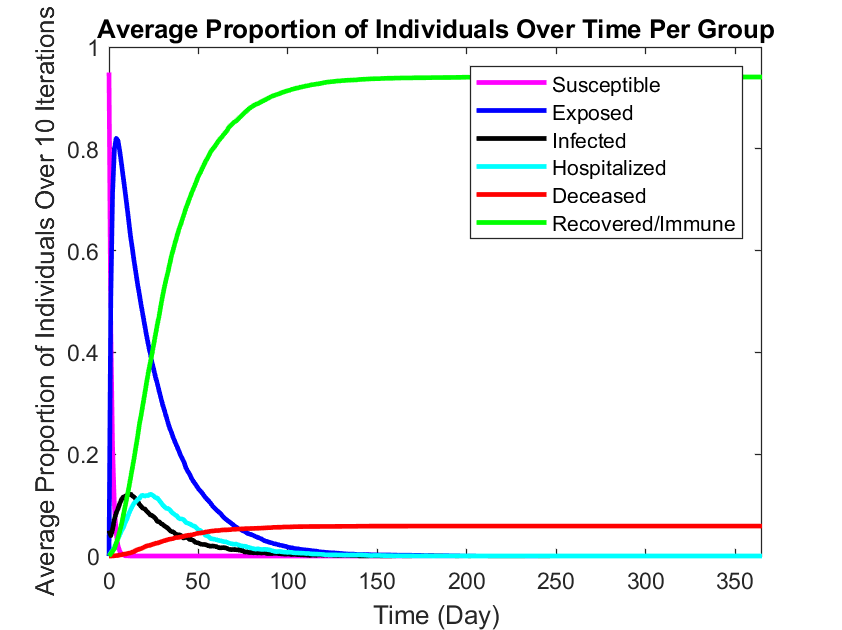

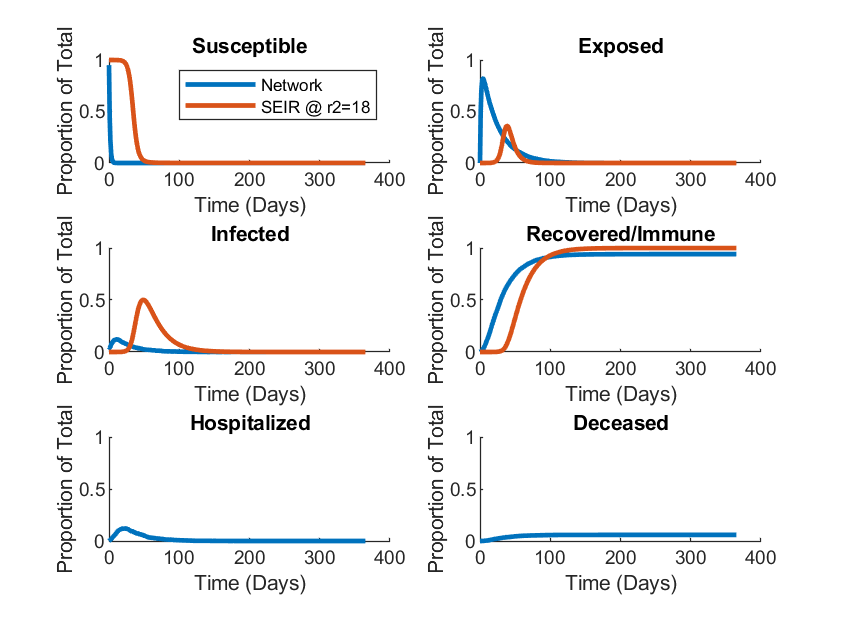

This table displays the maxima along the 
mean of 10 simulation iterations for each group 
and the times in which they occur 
for quarantining rate of 0.5.

                                         Max Susceptible    Max Exposed    Max Infected    Max Deceased    Max Hospitalized    Max Immune
                                         _______________    ___________    ____________    ____________    ________________    __________

    Proportions Across Simulation            0.4454           0.8209          0.1225          0.0589            0.1213           0.9411  
    Times for Max Average Proportions             1                4              12             181                23              247  



% Store infected/susceptible state to recall for all iterations
state_orig = state;

% RECAP: SUSCEPTIBLE = 0, INFECTED = 1, EXPOSED = 2, HOSPITALIZED = 3,
% RECOVERED/IMMUNE = 4, DEAD = NaN

% For each potential social distancing probability
for c = 1:11

    % Repeat model for 100 iterations to average findings
    for l = 1:100
        
        % initialize the iteration state of susceptible and infected to original state of infection
        state = state_orig; 
        
        % For each day in the year
        for day = 1:num_days      
            
            % For each individual in the contact network
            for i = 1:N                                 
                
                % If the individual is infected
                if state(i) == 1
                    
                    % Find the other individuals in the network they are in
                    % contact with 
                    contacts = find(network(i, :));     
                    
                    % For all contacts in network 
                    for j = contacts               
                        
                        % Randomly generate a number to decide chance of
                        % contact becoming exposed if susceptible
                        exposed_diceroll = rand;
    
                        % If contact is susceptible
                        if state(j) == 0
    
                           % generate random chance for not social distancing
                           social_dist_diceroll = rand; 
                           
                           % If individual didn't social distance
                           if social_dist_diceroll > socialdist_prob(c)
    
                                % See if the probability is within the expected for
                                % exposure
                                if exposed_diceroll < expose_prob 
        
                                    % If so, susceptible individual becomes exposed
                                    % to COVID
                                    state(j) = 2; 
                                end
                           end
                        end
                    end
    
                    % now move onto the current infected patient 
    
                    % Since the patient is infected, there is a chance they
                    % will recover 
                    
                    % Randomly generate this chance
                    recovery_diceroll = rand;
    
                    % Randomly generate a chance for hospitalization as well 
                    hospitalized_diceroll = rand;
                    % IMMUNITY LASTS ABOUT 500 DAYS (well within sim) https://www.medicalnewstoday.com/articles/how-long-do-covid-antibodies-stay-in-your-system
                    % If recovery chance is within expected probability
                    if recovery_diceroll < recover_prob
    
                        % Infected individual becomes susceptible again
                        % (disregard short-term immunity as individuals have
                        % been found to get covid multiple times) 
                        state(i) = 4; 
                    
                    % if chance not within recovery and hospitalization is
                    % probable
                    elseif recovery_diceroll > recover_prob && hospitalized_diceroll < hospitalization_rate
    
                        % infected individual instead becomes hospitalized
                        state(i) = 3;
                    end
                    
                % If the individual is not infected, but is exposed, 
                elseif state(i) == 2 
                    
                    % Generate random chance for individual to become infected
                    infected_diceroll = rand; 
    
                    % If chance is within expected
                    if infected_diceroll <  infect_prob
    
                        % Convert exposed individual to infected
                        state(i) = 1;
                    end
    
                % If individual is hospitalized
                elseif state(i) == 3   
                    
                    % Generate random recovery chance
                    recovery_diceroll = rand; 
    
                    % Generate random hospitalization chance
                    hospitalized_diceroll = rand;
    
                    % Generate random death chance
                    reaper_diceroll = rand;
                    
                    % IMMUNITY FOR 500 days (well within sim) https://www.medicalnewstoday.com/articles/how-long-do-covid-antibodies-stay-in-your-system
                    % If recovery is expected
                    if recovery_diceroll < recover_prob 
                        
                        % Hospitalized individual becomes susceptible and can
                        % go home
                        state(i) = 4;
                    
                    % If individual is still symptomatic and expected by chance
                    elseif hospitalized_diceroll < hospitalization_rate
    
                        % Remain in hospital
                        state(i) = 3; 
                    end
                    
                    % If the individual's age is less than or equal to 29
                    if age(i) <= 29

                        % Evaluate death roll vs. hospital death rate for
                        % this age range
                        if reaper_diceroll < hosp_death_rate_29

                            % Remove from matrix as deceased
                            state(i) = NaN;
                        end

                    % elseif the individual's age is less than or equal to
                    % 59
                    elseif age(i) <= 59
                        % Evaluate death roll vs. hospital death rate for
                        % this age range
                        if reaper_diceroll < hosp_death_rate_59

                            % Remove from matrix as deceased
                            state(i) = NaN;
                        end

                    % else the individual's age is considered > 59
                    else 

                        % Evaluate death roll vs. hospital death rate for
                        % this age range
                        if reaper_diceroll < hosp_death_rate_plus

                            % Remove from matrix as deceased
                            state(i) = NaN;
                        end
                    end

                % If susceptible, 
                elseif state(i) == 0 
                    social_dist_diceroll = rand; 
                    if social_dist_diceroll > socialdist_prob(c) % then did not social distance and gets exposed to covid-19
                        state(i) = 2;
                    end
                end
            end  

            % Record the number of exposed and infected individuals
            num_susceptible(day) = sum(state == 0);
            num_infected(day) = sum(state == 1);
            num_exposed(day) = sum(state == 2);
            num_hospitalized(day) = sum(state == 3);
            num_immune(day) = sum(state == 4); 
            num_deceased(day) = sum(isnan(state));
        end
    
    % Store all of the simulated data for this iteration in the accumulation
    % variables
    num_exposed_accumulated(l,:) = num_exposed';
    num_infected_accumulated(l,:) = num_infected';
    num_susceptible_accumulated(l,:) = num_susceptible';
    num_deceased_accumulated(l,:) = num_deceased'; 
    num_hospitalized_accumulated(l,:) = num_hospitalized';
    num_immune_accumulated(l, :) = num_immune';
    end

    % For the average quarantining/social distancing rate of 0.5, when c
    % == 6
    if c == 6

        % Display a message about the upcoming figure 
        fprintf('This figure displays the maxima along the \nmean of 10 simulation iterations for each group \nand the times in which they occur \nfor quarantining rate of 0.5.')   
        
        % Plot the number of exposed and infected individuals over time
        figure;
        
        % Plot susceptible
        plot(0:num_days, [initial_susceptible_proportion mean(num_susceptible_accumulated)/N], 'Color', 'Magenta', 'DisplayName', 'Susceptible', 'LineWidth', 2);
        hold on 
        % Plot exposed proportion 
        plot(0:num_days, [0 mean(num_exposed_accumulated)/N], 'Color', 'Blue', 'DisplayName', 'Exposed', 'LineWidth', 2);
        
        % Plot infectious proportion
        plot(0:num_days, [initial_infected_proportion mean(num_infected_accumulated)/N], 'Color', 'Black', 'DisplayName', 'Infected', 'LineWidth', 2);
        
        % Plot hospitalized proportion
        plot(0:num_days, [0 mean(num_hospitalized_accumulated)/N], 'Color', 'Cyan', 'DisplayName', 'Hospitalized', 'LineWidth', 2)
        
        % Plot deceased proportion
        plot(0:num_days, [0 mean(num_deceased_accumulated)/N], 'Color', 'Red', 'DisplayName', 'Deceased', 'LineWidth', 2)
        
        % Plot immune proportion
        plot(0:num_days, [0 mean(num_immune_accumulated)/N], 'Color', 'Green', 'DisplayName', 'Recovered/Immune', 'LineWidth', 2)
        % Label figure
        xlabel('Time (Day)');
        ylabel('Average Proportion of Individuals Over 10 Iterations');
        xlim([0 num_days])
        title('Average Proportion of Individuals Over Time Per Group')
        legend()

        % Hold off of the figure 
        hold off
    
        % Next we will generate subplots for the comparison of the network
        % model to the SEIR model
        figure
        hold on 

        % Susceptible subplot
        subplot(3,2,1)
        hold on 

        % Plot network results 
        plot(0:num_days, [initial_susceptible_proportion mean(num_susceptible_accumulated)/N], 'DisplayName', 'Network', 'LineWidth', 2);
        
        % Plot SEIR results
        plot(T,Y(:,1)./11081000, 'LineWidth', 2, 'DisplayName', 'SEIR @ r2=18')

        % Label figure 
        ylabel('Proportion of Total')
        title('Susceptible')
        xlabel('Time (Days)')
        ylim([0 1])
        legend
    
        % Exposed subplot
        subplot(3,2,2) 
        hold on 

        % Plot network results
        plot(0:num_days, [0 mean(num_exposed_accumulated)/N], 'DisplayName', 'Network', 'LineWidth', 2);

        % Plot SEIR results
        plot(T,Y(:,2)./11081000, 'LineWidth', 2, 'DisplayName', 'SEIR @ r2=18')

        % Label figure
        ylabel('Proportion of Total')
        title('Exposed')
        xlabel('Time (Days)')
        ylim([0 1])

        % Infected subplot
        subplot(3,2,3) 
        hold on 

        % Plot network results
        plot(0:num_days, [initial_infected_proportion mean(num_infected_accumulated)/N],'DisplayName', 'Network', 'LineWidth', 2);
        
        % Plot SEIR results
        plot(T,Y(:,3)./11081000, 'LineWidth', 2, 'DisplayName', 'SEIR @ r2=18')

        % Label figure
        ylabel('Proportion of Total')
        title('Infected')
        xlabel('Time (Days)')
        ylim([0 1])
    
        % Recovered subplot
        subplot(3,2,4) 
        hold on 

        % Plot network results
        plot(0:num_days, [0 mean(num_immune_accumulated)/N], 'DisplayName', 'Network', 'LineWidth', 2)
        
        % Plot SEIR results
        plot(T,Y(:,4)./11081000, 'LineWidth', 2, 'DisplayName', 'SEIR @ r2=18')

        % Label figure
        ylabel('Proportion of Total')
        title('Recovered/Immune')
        xlabel('Time (Days)')
        ylim([0 1])
    
        % Hospitalized subplot
        subplot(3,2,5) 
        hold on

        % Plot network results
        plot(0:num_days, [0 mean(num_hospitalized_accumulated)/N], 'DisplayName', 'Network', 'LineWidth', 2)
        
        % Label figure
        ylabel('Proportion of Total')
        title('Hospitalized')
        xlabel('Time (Days)')
        ylim([0 1])
    
        % Deceased Subplot
        subplot(3,2,6)
        hold on

        % Network results
        plot(0:num_days, [0 mean(num_deceased_accumulated)/N], 'DisplayName', 'Network', 'LineWidth', 2)
        
        % Label figure
        ylabel('Proportion of Total')
        title('Deceased')
        xlabel('Time (Days)')
        ylim([0 1])

    end

    % Calculate Average for each iteration 

    % Mean Peak Susceptible
    avg_susceptible = mean(num_susceptible_accumulated); 
    % Mean Peak Exposed
    avg_exposed = mean(num_exposed_accumulated);
    % Mean Peak Infected 
    avg_infected = mean(num_infected_accumulated);
    % Mean Peak Deceased
    avg_deceased = mean(num_deceased_accumulated);
    % Mean Peak Hospitalized
    avg_hospitalized = mean(num_hospitalized_accumulated);
    % Mean Peak Immune
    avg_immune = mean(num_immune_accumulated);
    
    % Calculuate maximum of average of each iteration

    % Susceptible
    max_susceptible = max(avg_susceptible);
    % Exposed
    max_exposed = max(avg_exposed);
    % Infected
    max_infected = max(avg_infected);
    % Deceased
    max_deceased = max(avg_deceased);
    % Hospitalized
    max_hospitalized = max(avg_hospitalized);
    % Immune
    max_immune = max(avg_immune);

    % Find times corresponding with maxima

    % Susceptible
    time_susceptible = find(avg_susceptible == max_susceptible);
    % Exposed
    time_exposed = find(avg_exposed == max_exposed);
    % Infected
    time_infected = find(avg_infected == max_infected);
    % Deceased
    time_deceased = find(avg_deceased == max_deceased);
    % Hospitalized
    time_hospitalized = find(avg_hospitalized == max_hospitalized);
    % Immune
    time_immune = find(avg_immune == max_immune);
    
    % Concatenate the results for the quarantining rate iteartion
    max_c(:,c) =[max_susceptible/N;max_exposed/N; max_infected/N; max_deceased/N; max_hospitalized/N; max_immune/N];
    time_c(:,c) = [time_susceptible(1); time_exposed(1);time_infected(1); time_deceased(1); time_hospitalized(1); time_immune(1)];
    
    % For quarantining rate = 0.5, display a table of results
    if c == 6
        fprintf('This table displays the maxima along the \nmean of 10 simulation iterations for each group \nand the times in which they occur \nfor quarantining rate of 0.5.') 
        t1 = table([max_susceptible/N; time_susceptible(1)], [max_exposed/N; time_exposed(1)], [max_infected/N; time_infected(1)], [max_deceased/N; time_deceased(1)], [max_hospitalized/N; time_hospitalized(1)], [max_immune/N; time_immune(1)]);
        t1.Properties.VariableNames = {'Max Susceptible', 'Max Exposed', 'Max Infected', 'Max Deceased', 'Max Hospitalized', 'Max Immune'};
        t1.Properties.RowNames = {'Proportions Across Simulation', 'Times for Max Average Proportions'};
        disp(t1)    
    end
end

#### Step 3. Parametric Analysis by Social Distancing/Isolating/Quaranting

#### Separated groups across quarantining rate

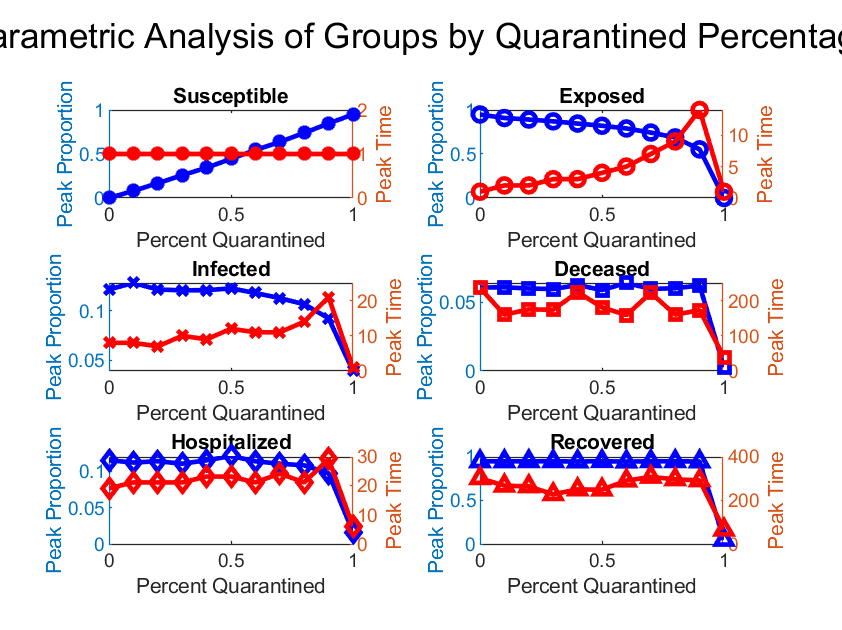

% Generate a new figure 
figure

% Give it an overarching title
sgtitle('Parametric Analysis of Groups by Quarantined Percentage')
hold on 

% For each subgroup
for k = 1:6 

    % If susceptible
    if k == 1

        % First subplot
        subplot(3,2,1)

        % On left y-axis
        yyaxis left

        % Plot peak proportion
        plot(socialdist_prob, max_c(k,:), '-b*', 'LineWidth', 2,'DisplayName', 'Susceptible')
        ylabel('Peak Proportion')
        
        % On right y-axis
        yyaxis right

        % Plot peak time in days
        plot(socialdist_prob, time_c(k,:),'-r*','LineWidth', 2, 'DisplayName', 'Susceptible')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        
        % Add title 
        title('Susceptible')

    % If exposed 
    elseif k == 2

        % Second subplot
        subplot(3,2,2)

        % On left y-axis
        yyaxis left

        % Plot peak proportion
        plot(socialdist_prob, max_c(k,:), '-bo','LineWidth', 2,'DisplayName', 'Exposed')
        ylabel('Peak Proportion')
        
        % On right y-axis 
        yyaxis right

        % Plot peak time 
        plot(socialdist_prob, time_c(k,:),'-ro', 'LineWidth', 2, 'DisplayName', 'Exposed')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        
        % Add title
        title('Exposed')
    
    % If infected, follow similar commenting 
    elseif k == 3
        subplot(3,2,3)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-bx','LineWidth', 2,'DisplayName', 'Infected')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:), '-rx','LineWidth', 2, 'DisplayName', 'Infected')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Infected')
    
    % If deceased, follow similar commenting
    elseif k == 4
        subplot(3,2,4)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-bs','LineWidth', 2,'DisplayName', 'Diseased')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:), '-rs','LineWidth', 2, 'DisplayName', 'Diseased')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Deceased')

    % If Hospitalized, follow similar commenting
    elseif k == 5
        subplot(3,2,5)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-bd','LineWidth', 2,'DisplayName', 'Hospitalized')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:), '-rd','LineWidth', 2, 'DisplayName', 'Hospitalized')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Hospitalized')
    
    % If recovered, follow similar commenting
    elseif k == 6
        subplot(3,2,6)
        yyaxis left
        plot(socialdist_prob, max_c(k,:), '-b^','LineWidth', 2,'DisplayName', 'Recovered')
        ylabel('Peak Proportion')
        yyaxis right
        plot(socialdist_prob, time_c(k,:), '-r^','LineWidth', 2, 'DisplayName', 'Recovered')
        xlabel('Percent Quarantined')
        ylabel('Peak Time')
        title('Recovered')
    end
end

#### Peak proportions across quarantining rates

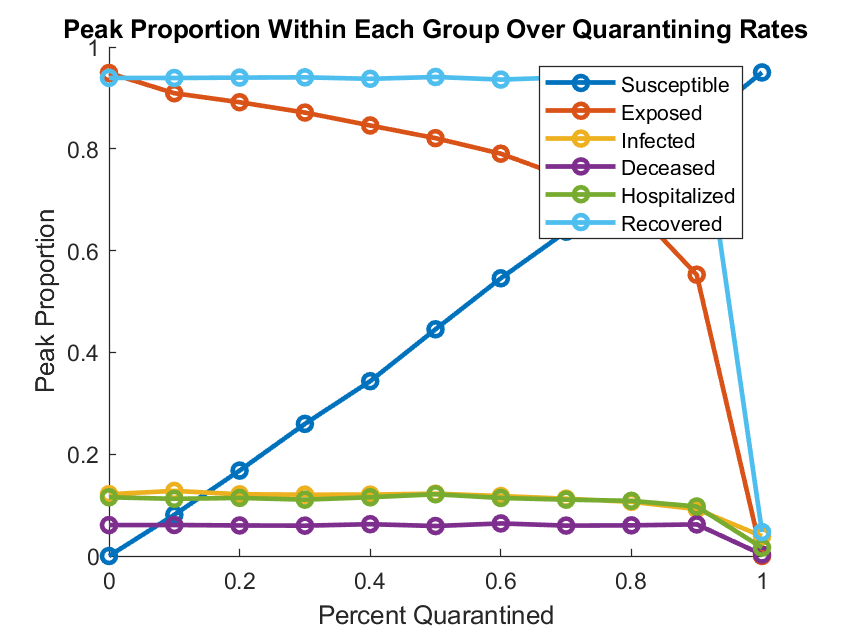

% New figure 
figure
hold on 

% Plot all groups over quarantining rates
for k = 1:6 
    if k == 1
        plot(socialdist_prob, max_c(k,:), '-o','LineWidth', 2,'DisplayName', 'Susceptible')
    elseif k == 2
        plot(socialdist_prob, max_c(k,:),'-o', 'LineWidth', 2,'DisplayName', 'Exposed')
    elseif k == 3
        plot(socialdist_prob, max_c(k,:),'-o', 'LineWidth', 2,'DisplayName', 'Infected')
    elseif k == 4
        plot(socialdist_prob, max_c(k,:),'-o', 'LineWidth', 2,'DisplayName', 'Deceased')
    elseif k == 5
        plot(socialdist_prob, max_c(k,:),'-o', 'LineWidth', 2,'DisplayName', 'Hospitalized')
    elseif k == 6
        plot(socialdist_prob, max_c(k,:), '-o', 'LineWidth', 2,'DisplayName', 'Recovered')
    end
end

% Label figure
xlabel('Percent Quarantined')
legend
ylabel('Peak Proportion')
title('Peak Proportion Within Each Group Over Quarantining Rates')
hold off

#### Times at peak proportions across quarantining rates

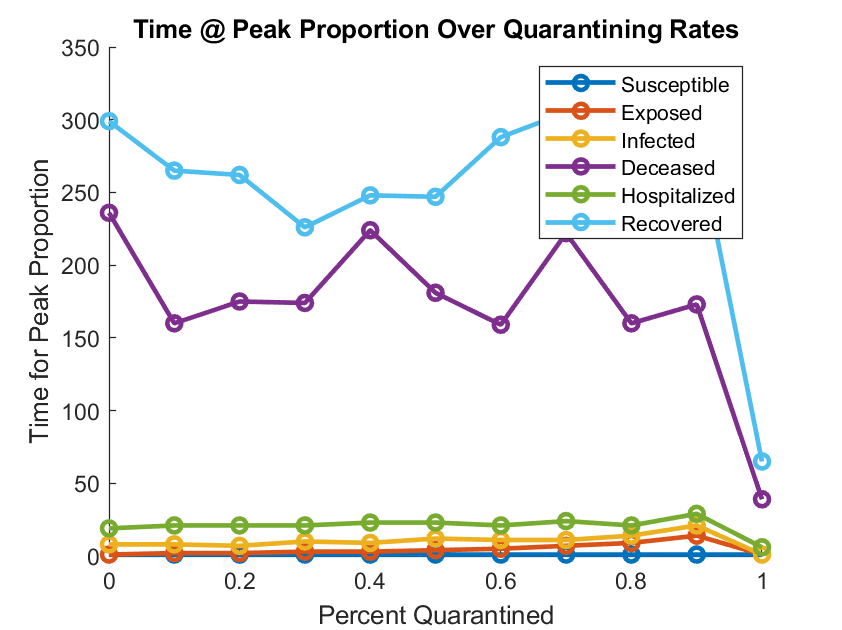

% New figure 
figure
hold on 

% For each group, plot time at peak proportion with similar commenting
for k = 1:6 
    if k == 1
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Susceptible')
    elseif k == 2
        plot(socialdist_prob, time_c(k,:),'-o', 'LineWidth', 2, 'DisplayName', 'Exposed')
    elseif k == 3
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Infected')
    elseif k == 4
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Deceased')
    elseif k == 5
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Hospitalized')
    elseif k == 6
        plot(socialdist_prob, time_c(k,:), '-o','LineWidth', 2, 'DisplayName', 'Recovered')
    end
end
xlabel('Percent Quarantined')
legend
ylabel('Time for Peak Proportion')
title('Time @ Peak Proportion Over Quarantining Rates')